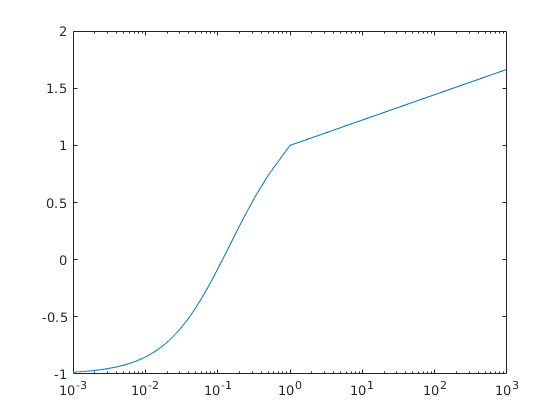

% problem 4.13 - mass spring system

% constants
L = 1;
k1 = 1;
k2 = linspace(1/1000, 1000, 1000);

for i = 1:length(k2)
    K = [2*k1 - k2(i), k1, k2(i);...
         k1, -2*k1 - k2(i), k1;...
         k2(i), k1, -k1 - k2(i)];
    b = [k2(i) * L;...
         -k2(i) * L;...
         -L*(k1+k2(i))];
    x = K \ b;
    x4(i) = x(3);
end

semilogx((1./k2), x4)